clear
load("/Users/charlesliu/Desktop/LI_project/MNIST_cycle2_nomerge.mat");
SetRNG(111)

ans = struct with fields:
     Type: 'simdTwister'
     Seed: 111
    State: [776×1 uint32]


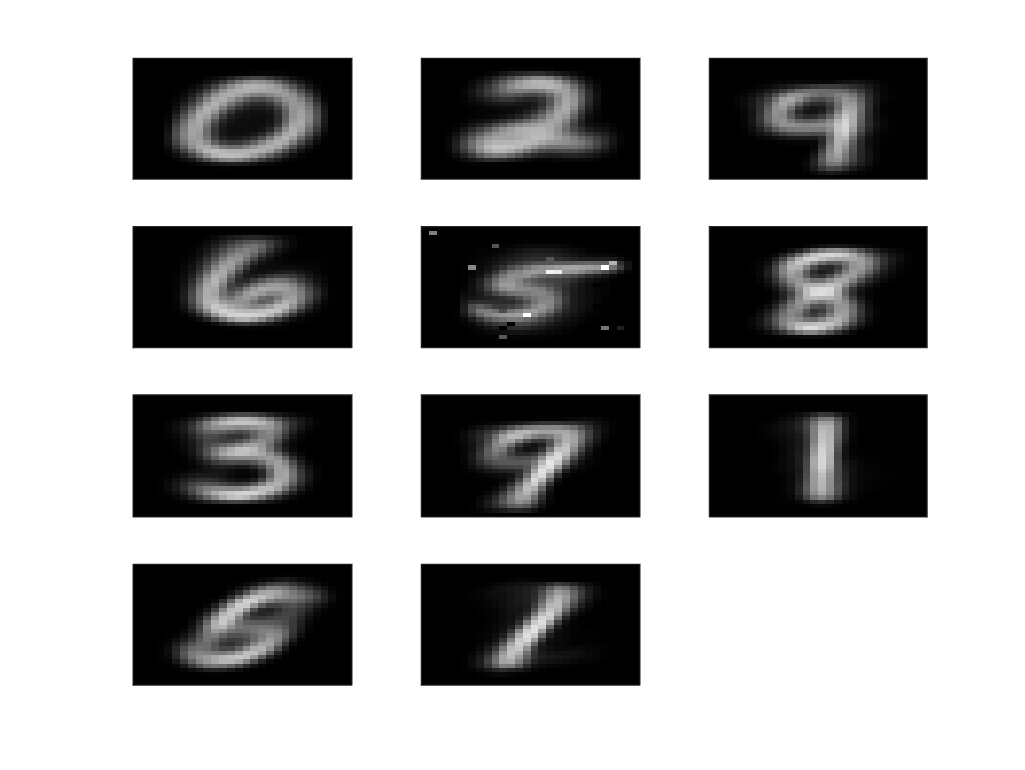

cycle2_winner_demask = [];
for i = 1:length(cluster_distribution);%length(id); 
subplot(4,3,i)
k = cluster_distribution(i,1);
colormap(gray(256))
images = ori_cycle2_cells(:,cycle2_winners_mask(k))+pre_winner;
cycle2_winner_demask = [cycle2_winner_demask,images];
image(reshape(images,28,28))
set(gca,'XTick',[], 'YTick', [])
%pause(0.2);
end


unique_cluster = unique(clustAssignments);
cluster_label = [clustAssignments,assign_id];
subdivi_winner_idx = [];
for i = 1:length(unique_cluster)
    assigned = unique_cluster(i);
    labels = cluster_label(find(cluster_label(:,1) == assigned),2);
    num_max_class = numel(find(labels==mode(labels)));

    if length(unique(labels)) == 1 | num_max_class/length(labels) >= 0.65;
        %disp('cluster with index1 '+string(i)+' and index2 '+string(assigned)+' is not subdivisible')
    else
        disp('cluster with index1 '+string(i)+' and index2 '+string(assigned)+' is subdivisible')
        subdivi_winner_idx = [subdivi_winner_idx;assigned];
    end
end

cluster with index1 3 and index2 167 is subdivisible
cluster with index1 7 and index2 273 is subdivisible
cluster with index1 8 and index2 278 is subdivisible
cluster with index1 10 and index2 425 is subdivisible
cluster with index1 11 and index2 494 is subdivisible


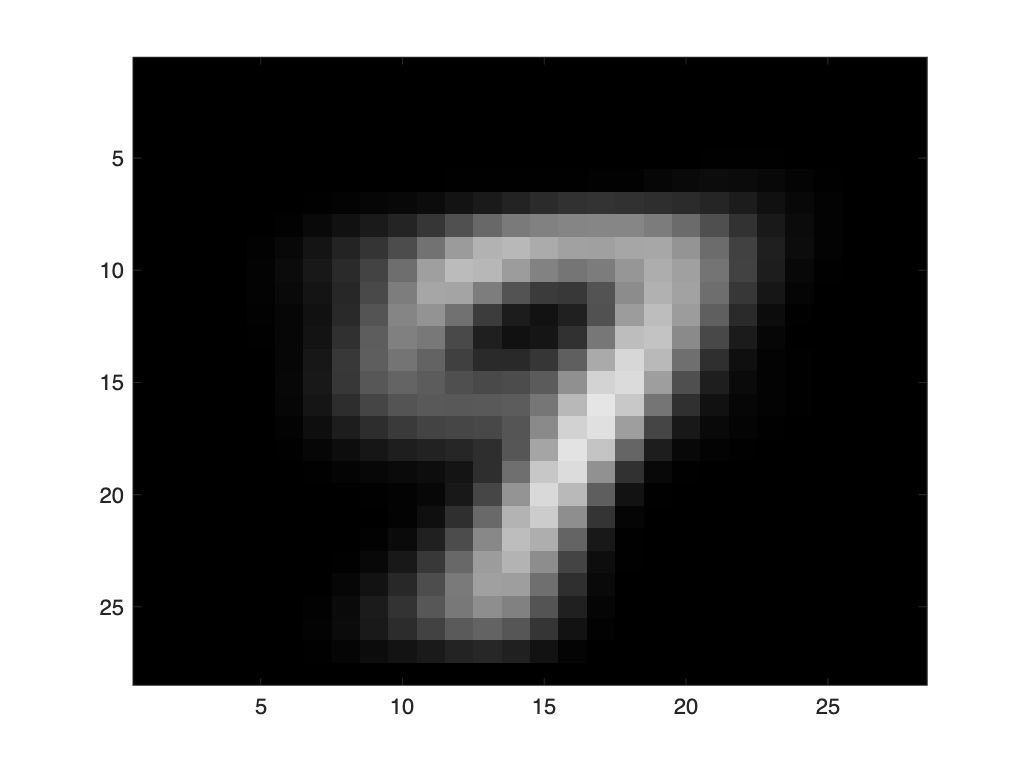

k = 8;
cycle_2_center = unique_cluster(k);
%cycle 2 winner plot
figure;
colormap(gray(256))
image(reshape(pre_winner+ori_cycle2_cells(:,cycle_2_center),28,28))


assigned = cycle_2_center;
labels = cluster_label(find(cluster_label(:,1) == assigned),2);
[GC,GR] = groupcounts(labels);

PTY1_noMerge = purity(clustAssignments,assign_id)

PTY1_noMerge = 0.6205

NMI1_noMerge = nmi(assign_id, clustAssignments)

NMI1_noMerge = 0.5189

[RI1_noMerge, ARI1_noMerge] = randindex(assign_id, clustAssignments)

RI1_noMerge = 0.8920

ARI1_noMerge = 0.4063

%[s1_noMerge] = ClusterEvalSilhouette (X', clustAssignments, 'cosine')
ch1_noMerge = ClusterEvalCalinskiHarabasz(X', clustAssignments)

ch1_noMerge = 361.6119

[db1_noMerge] = ClusterEvalDaviesBouldin (X', clustAssignments)

db1_noMerge = 2.7510

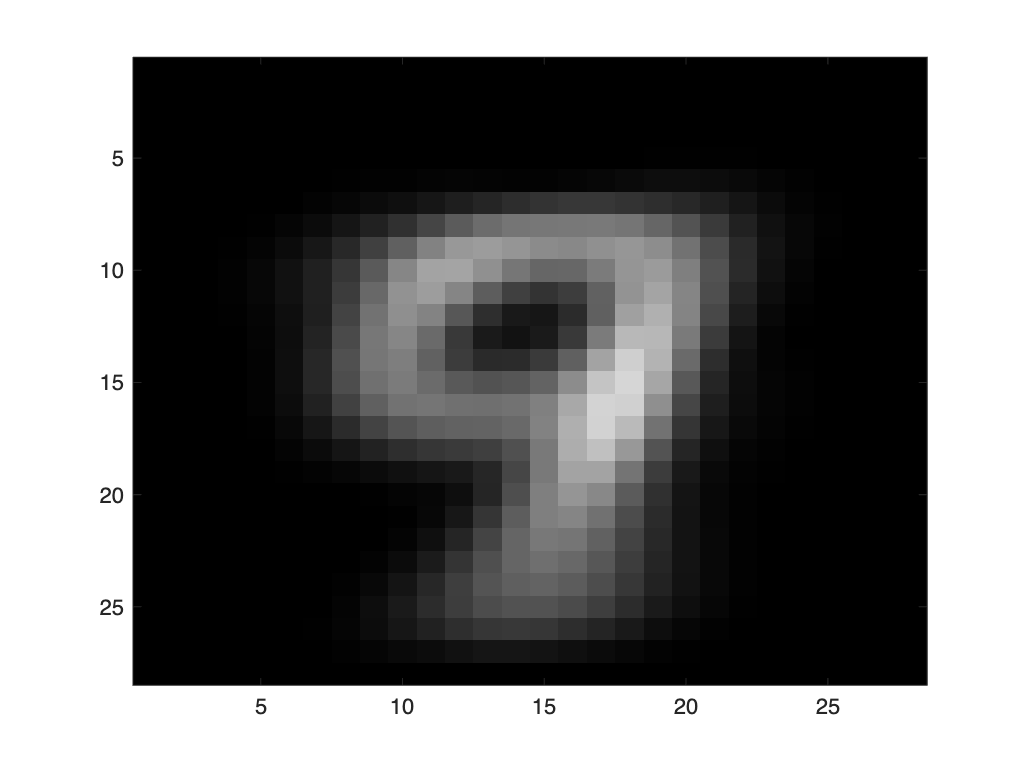

% merge, after merge check again
dat_id_4_merge = [];
winner_id_4_merge = [3,8];

for i = winner_id_4_merge;
    assigned = unique_cluster(i);
    merge = find(cluster_label(:,1) == assigned);
    dat_id_4_merge = [dat_id_4_merge;merge];
end
new_centroid = mean(ori_cycle2_cells(:,unique_cluster(winner_id_4_merge)),2);
figure;
colormap(gray(256))
image(reshape(pre_winner+new_centroid,28,28))

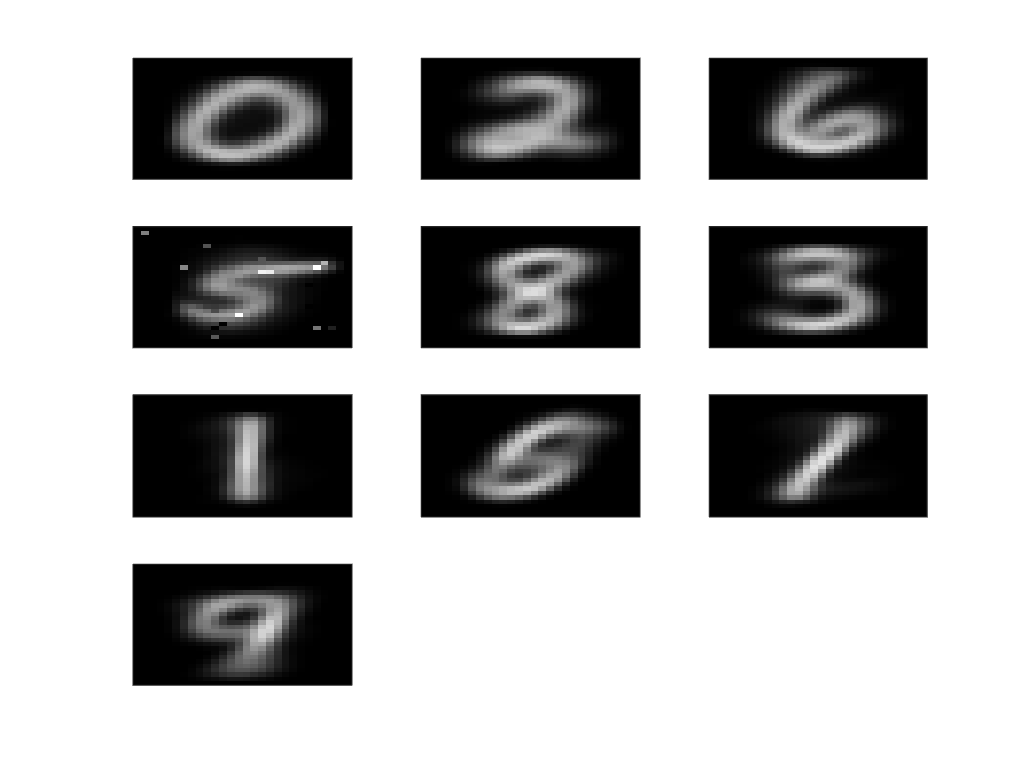

ori_cycle2_cells = [ori_cycle2_cells,new_centroid];
clustAssignments(dat_id_4_merge) = size(ori_cycle2_cells,2);


unique_cluster = unique(clustAssignments);
cluster_label = [clustAssignments,assign_id];
for i = 1:length(unique_cluster);%length(id); 
subplot(4,3,i)
k = unique_cluster(i);
colormap(gray(256))
images = ori_cycle2_cells(:,k)+pre_winner;
%cycle2_winner_demask = [cycle2_winner_demask,images];
image(reshape(images,28,28))
set(gca,'XTick',[], 'YTick', [])
end



subdivi_winner_idx = [];
for i = 1:length(unique_cluster)
    assigned = unique_cluster(i);
    labels = cluster_label(find(cluster_label(:,1) == assigned),2);
    num_max_class = numel(find(labels==mode(labels)));

    if length(unique(labels)) == 1 | num_max_class/length(labels) >= 0.65;
        %disp('cluster with index1 '+string(i)+' and index2 '+string(assigned)+' is not subdivisible')
    else
        disp('cluster with index1 '+string(i)+' and index2 '+string(assigned)+' is subdivisible')
        subdivi_winner_idx = [subdivi_winner_idx;assigned];
    end
end

cluster with index1 6 and index2 273 is subdivisible
cluster with index1 8 and index2 425 is subdivisible
cluster with index1 9 and index2 494 is subdivisible
cluster with index1 10 and index2 501 is subdivisible



[Lia,Locb] = ismember(cluster_label(:,1),subdivi_winner_idx);
sub_divide_data_idx = find(Lia==1);
sub_cluster_label = cluster_label(sub_divide_data_idx,:);
non_sub_divide_data_idx = setdiff(1:length(Locb),sub_divide_data_idx)';

PTY1_merge = purity(clustAssignments,assign_id)

PTY1_merge = 0.5974

NMI1_merge = nmi(assign_id, clustAssignments)

NMI1_merge = 0.5357

[RI1_merge, ARI1_merge] = randindex(assign_id, clustAssignments)

RI1_merge = 0.8747

ARI1_merge = 0.4089

[s1_merge] = ClusterEvalSilhouette (X', clustAssignments, 'cosine')

s1_merge = 0.1236

ch1_merge = ClusterEvalCalinskiHarabasz(X', clustAssignments)

ch1_merge = 359.6764

[db1_merge] = ClusterEvalDaviesBouldin (X', clustAssignments)

db1_merge = 2.7190

% cycle 3
cycle = 3;
ori_cycle3_cells = ori_cycle2_cells;
cycle3_cells = normc(ori_cycle2_cells);
cycle3_cells_iter = normc(ori_cycle2_cells);

cycle2_winners = [cycle2_winners_mask;501];
ori_cycle3_cells(:,cycle2_winners) = 0;
cycle3_cells(:,cycle2_winners) = 0;
cycle3_cells_iter(:,cycle2_winners) = 0;

cycle3_assignment = {};
cycle3_subdata = {};
cycle3_subdata_winner = {};
%trimmed_cycle1_winner = unique(winner_id);
%SetRNG(111);
subdivi_winner_idx = subdivi_winner_idx(randperm(size(subdivi_winner_idx, 1)));
sub_divide_assign = zeros(length(clustAssignments),1);
cycle3_subdata_global_idx = {};

for c1 = 1:length(subdivi_winner_idx);
    c2 = subdivi_winner_idx(c1);
    this_winner_1 = pre_winner;
    this_winner_2 = ori_cycle2_cells(:,c2);
    sampled_data_new = X(:,find(clustAssignments == c2));

    cycle3_subdata_global_idx{c1} = find(clustAssignments == c2);
    sampled_data_fix = sampled_data_new-this_winner_1-this_winner_2;
    cycle3_subdata{c1} = sampled_data_fix; % subdivisive datasets after cycle 2

    lr = 0.001;
    for k = 1:20; 
        winner_len_mat = [];
        cycle3_winners = [];
        sampled_data = sampled_data_fix(:, randperm(size(sampled_data_fix, 2)));
        winner_average = zeros(784,1,8000);
        for col = 1:size(sampled_data,2); % loop over all inputs
            input1 = sampled_data(:,col);
            len_input = norm(input1);
            input1 = normc(input1);
            product = input1'*cycle3_cells; % the  dot products of the input and all cells
            winning_value = max(product); % max dot product value
            winning_idx = find(product == winning_value);
            winning_cell = cycle3_cells_iter(:,winning_idx);
            cycle3_winners = [cycle3_winners;winning_idx];
            winner_len_mat = [winner_len_mat;[winning_idx,len_input]];
            update_winner = winning_cell+(input1-winning_cell)*lr;
            winner_average(:,:,winning_idx) = update_winner + winner_average(:,:,winning_idx);
            cycle3_cells_iter(:,winning_idx) = update_winner;
            update_winner = normc(update_winner);
            cycle3_cells(:,winning_idx) = update_winner;
        end
    end

    [~,~,ix] = unique(cycle3_winners,"stable");
    winner_stats = [unique(cycle3_winners,"stable"),accumarray(ix,1)];
    for i = 1:size(winner_stats,1);
        winner_average(:,:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1))./winner_stats(i,2);
        cycle3_cells_iter(:,winner_stats(i,1)) = winner_average(:,:,winner_stats(i,1));
    end

    cycle3_winners = unique(cycle3_winners);
    for c = cycle3_winners';
        each_input = winner_len_mat(winner_len_mat(:,1)== c,2);
        ori_cycle3_cells(:,c) = cycle3_cells_iter(:,c)*mean(each_input);
    end

    [~,idx] = max(normc(sampled_data_fix)'*cycle3_cells(:,cycle3_winners),[],2);
    sub_divide_assign(find(clustAssignments == c2)) = cycle3_winners(idx);
    cycle3_subdata_winner{c1} = cycle3_winners(idx);
    [GC,GR] = groupcounts(cycle3_winners(idx));
    cluster_distribution = [GR,GC];
    cycle3_cells(:,cycle3_winners) = 0;
    cycle3_cells_iter(:,cycle3_winners) = 0;
    cycle3_assignment{c1} = cluster_distribution;
end

% scores before removing outliers
sub_divide_assign(non_sub_divide_data_idx) = clustAssignments(non_sub_divide_data_idx);
PTY2 = purity(sub_divide_assign,assign_id)

PTY2 = 0.7444

NMI2 = nmi(assign_id, sub_divide_assign)

NMI2 = 0.5397

[RI2, ARI2] = randindex(assign_id, sub_divide_assign)

RI2 = 0.9131

ARI2 = 0.3901

[s2_nomerge] = ClusterEvalSilhouette (X', sub_divide_assign, 'cosine')

s2_nomerge = -0.0604

ch2 = ClusterEvalCalinskiHarabasz(X', sub_divide_assign)

ch2 = 99.4834

[db2] = ClusterEvalDaviesBouldin (X', sub_divide_assign)

db2 = 1.8795


% scores after removing outliers only 
nondegen_cluster = sub_divide_assign;
nondegen_id = assign_id;
nondegen_data = X;
[GC,GR] = groupcounts(nondegen_cluster); 
delete_idx = find(ismember(nondegen_cluster,GR(find(GC<30))));
nondegen_cluster(delete_idx) = [];
nondegen_id(delete_idx) = [];
nondegen_data(:,delete_idx) = [];

PTY2_remove = purity(nondegen_cluster,nondegen_id)

PTY2_remove = 0.7426

NMI2_remove = nmi(nondegen_id, nondegen_cluster)

NMI2_remove = 0.5432

[RI2_remove, ARI2_remove] = randindex(nondegen_id, nondegen_cluster)

RI2_remove = 0.9133

ARI2_remove = 0.3970

[s2_remove] = ClusterEvalSilhouette (nondegen_data', nondegen_cluster, 'cosine')

s2_remove = 0.0557

ch2_remove = ClusterEvalCalinskiHarabasz(nondegen_data', nondegen_cluster)

ch2_remove = 153.2086

[db2_remove] = ClusterEvalDaviesBouldin (nondegen_data', nondegen_cluster)

db2_remove = 2.8180


% 
% % reassignment after remove()
% reass_cycle3_assignment = {};
% reass_for_score = sub_divide_assign;
% for i = 1:length(cycle3_assignment);
%     sub_assign_c3 = cycle3_assignment{i}(:,2);
%     dominant_labels = cycle3_assignment{i}(sub_assign_c3>20,1);
%     outlier_labels = cycle3_assignment{i}(sub_assign_c3<=20,1);
%     reassign_data = cycle3_subdata{i};
%     reassign_data_winner = cycle3_subdata_winner{i};
%     reassign_data_idx = find(ismember(reassign_data_winner,outlier_labels) == 1);
%     dominant_winner = normc(ori_cycle3_cells(:,dominant_labels));
%     [~,reass_idx] = max(normc(reassign_data(:,reassign_data_idx))'*dominant_winner,[],2);
%     reassign_data_winner(reassign_data_idx) = dominant_labels(reass_idx);
%     [GC,GR] = groupcounts(reassign_data_winner); 
%     reass_cycle3_assignment{i} = [GR,GC];
%     %reass_for_score() = reassign_data_winner;
%     %reass_for_score(find(ismember(reass_for_score,outlier_labels) == 1)) = dominant_labels(reass_idx);
% end


% PTY2 = purity(reass_for_score,assign_id)
% NMI2 = nmi(assign_id, reass_for_score)
% [RI2, ARI2] = randindex(assign_id, reass_for_score)
% [s2] = ClusterEvalSilhouette (X', reass_for_score, 'cosine')
% ch2 = ClusterEvalCalinskiHarabasz(X', reass_for_score)
% [db2] = ClusterEvalDaviesBouldin (X', reass_for_score)


cycle3_winner_demask = [];
cycle3_assignment_removed = {}
for i = 1:length(cycle3_assignment);
    cycle_2_center = subdivi_winner_idx(i);
    cycle3_distribution = cycle3_assignment{i};
    cycle3_distribution(find(cycle3_distribution(:,2)<30),:) = [];
    cycle3_assignment_removed{i} = cycle3_distribution;
    images = pre_winner+ori_cycle2_cells(:,cycle_2_center)+ori_cycle3_cells(:,cycle3_distribution(:,1));
    cycle3_winner_demask = [cycle3_winner_demask,images];
end

k = 4;
cycle_2_center = subdivi_winner_idx(k);
cycle3_distribution = cycle3_assignment_removed{k};
sub_cluster_label = [nondegen_cluster,nondegen_id];
unique_cluster = cycle3_distribution(:,1);
figure;
colormap(gray(256))
image(reshape(pre_winner+ori_cycle2_cells(:,cycle_2_center),28,28))

%cycle 3 winner plot
figure;
for i = 1:size(cycle3_distribution,1);%length(id); 
subplot(4,3,i)
K = cycle3_distribution(i,1);
colormap(gray(256))
images = pre_winner+ori_cycle2_cells(:,cycle_2_center)+ori_cycle3_cells(:,K);
image(reshape(images,28,28))
set(gca,'XTick',[], 'YTick', [])
%pause(0.2);
end


for i = 1:length(unique_cluster)
    assigned = unique_cluster(i);
    labels = sub_cluster_label(find(sub_cluster_label(:,1) == assigned),2);
    [GC,GR] = groupcounts(labels); 
    num_max_class = numel(find(labels==mode(labels)));

    if length(unique(labels)) == 1 | num_max_class/length(labels) >= 0.5;
        disp('cluster with winner index '+string(assigned)+' is not subdivisible')
    else
        disp('cluster with winner index '+string(assigned)+' is subdivisible')
    end
end

assigned = 442;
labels = sub_cluster_label(find(sub_cluster_label(:,1) == assigned),2);
[GC,GR] = groupcounts(labels); 
[GC,GR]

MNIST_LIHC_MERGE_DEN.clustAssignments = clustAssignments;
MNIST_LIHC_MERGE_DEN.cycle3_assignment = cycle3_assignment;
MNIST_LIHC_MERGE_DEN.sub_divide_assign = sub_divide_assign;
MNIST_LIHC_MERGE_DEN.subdivi_winner_idx = subdivi_winner_idx;
MNIST_LIHC_MERGE_DEN.X = X;
save("MNIST_LIHC_MERGE_DEN.mat","-struct","MNIST_LIHC_MERGE_DEN")